
% figure Precession 10s %

clear all;
close all;

load('\\Artemis-pc\e\Data\2024-07-06\Abs-63\Fit.mat');


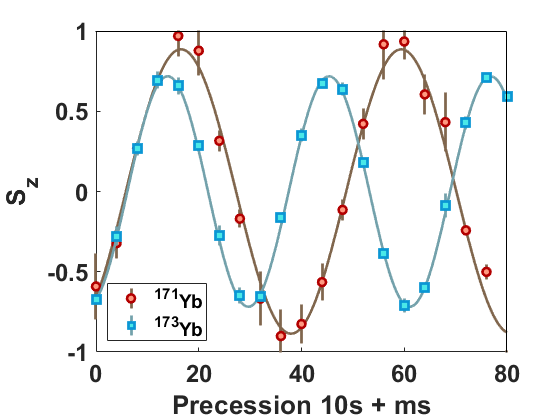


f1 = figure; hold on;
l1 = plot(fitresult, xData, yData);
I1 = errorbar(xData,yData,phase_std./sqrt(repeat_se-1),'square',MarkerSize=8);

l2 = plot(fitresult2, xData2, yData2);
I2 = errorbar(xData2,yData2,phase_std2./sqrt(repeat_se2-1),'o',MarkerSize=6);

l1(1).Marker = '.';
l1(1).MarkerSize = 0.1;
l1(2).Color = [0.45 0.63 0.67];
l1(2).LineWidth = 2;

I1.MarkerEdgeColor = [0.04 0.59 0.83];
I1.MarkerFaceColor = [0.29 0.91 0.91];
I1.CapSize = 0;
I1.LineWidth = 2;
I1.Color = [0.45 0.63 0.67];

l2(1).Marker = '.';
l2(1).MarkerSize = 0.1;
l2(2).Color = [0.5 0.4 0.3];
l2(2).LineWidth = 2;

I2.MarkerEdgeColor = [0.7 0 0];
I2.MarkerFaceColor = [1 0.6 0.5];
I2.CapSize = 0;
I2.Color = [0.5 0.4 0.3];
I2.LineWidth = 2;

xlabel( 'Precession 10s + ms' );
ylabel( 'S_z' );
%title(['Precession signal'],'FontName','Arial','FontWeight','bold');
set(gca,'FontSize',18,'FontName','Arial','FontWeight','bold',...
    'child',[I1,l1(1),l1(2),I2,l2(1),l2(2)]);

% legend('','',['a-171 = ',num2str(roundn(amp2(k),-3),'%.3f'),'(',num2str(round(a_sigma2(k)*1000)),')',...
%     newline 'T-171 = ',num2str(roundn(T2(k),-1),'%.3f'),'(',num2str(round(T_sigma2(k)*1000)),')'],...
%     '','',['a-173 = ',num2str(roundn(amp(k),-3),'%.3f'),'(',num2str(round(a_sigma(k)*1000)),')',...
%     newline 'T-173 = ',num2str(roundn(T(k),-1),'%.3f'),'(',num2str(round(T_sigma(k)*1000)),')'],...
%     'Location','best','FontSize',12);

legend({'','','^{171}Yb',...
    '','','^{173}Yb'},...
    'Location','southwest','FontName','Arial',...
    'FontWeight','bold','FontSize',14);

xlim([x_lim_low,x_lim_high]);
ylim([-1 1]);

grid off;
box off;

ax = axes('Position',get(gca,'Position'),'Color','none',...
    'XAxisLocation','top','YAxisLocation','right',...
    'XColor','k','YColor','k');
set(ax,'XTick',[]);
set(ax,'YTick',[]);


hold off;

set(f1,'Visible','on');


savefig(f1,'E:\Comagnetometer_Pub\Precession10s\Precession10s.fig');
saveas(f1,'E:\Comagnetometer_Pub\Precession10s\Precession10s.png');
saveas(f1,'E:\Comagnetometer_Pub\Precession10s\Precession10s.eps','psc');
saveas(f1,'E:\Comagnetometer_Pub\Precession10s\Precession10s.svg')


save('E:\Comagnetometer_Pub\Precession10s\Precession10s.mat');